## Generating Images and Postprocessing

This is a livescript, similar to a jupyter notebook in python. 

Use these controls. Primarly the "Run and Advance" button. 

This document will serve as a reference for running data, in this case the turbulent data.

-Add our paths to our dependency

addpath('plotting_camera');     % Additional codes incase of missing packages. 
addpath('ptvcodes');            % Post Processing codes
addpath('extracodes\')          % Extra codes and helper functions
addpath(genpath('dependency')); % Folder containing a core PTV folder dependency. 

**Generate a new working folder **

% Name of our new working folder 
folder_name = 'JHU_test_new';        % INPUT % 

% No Inputs % 
% Put all new test cases into a folder called "Test Cases" 
folder_path = ['test cases\',folder_name]
if exist(folder_path)
    disp('Folder exist')
else
    % make that folder 
    mkdir(folder_path);
    % copy default contents into our new working folder 
    copyfile('dependency\Base_test_folder\',folder_path);
end
% Add new folder path 
addpath(genpath(folder_path));

**Specify our working folder**

% Working folder
work_dir = folder_path;

## Setting up our synthetic Camera configuration:

**1.default_camera**

Setting up the default camera parameters can be done by opening the defaultcamera.m and adjusting the values within the function.

open('defaultCamera.m')

**2. Setting up default camera Arrangement.**

The default camera arrangement is set in the defaultCameraArrangement.m file. 

Setting up the default camera Arrangement can be done by opening the defaultCameraArrangement.m and adjusting the values within the function. The function uses x_p y_p z_p inputs, i.e offsets and deals them out accordingly for each respective camera. 

open('defaultCameraArrangement.m');

or we can generate the structure, then update the values.

CAMERAS = defaultCameraArrangement();
% well make the structure into a table so it easily seen
T = struct2table(CAMERAS);
T(:,1:6)

ans = 4×6 table
    FocalLength    PixelHeight    PixelWidth    PixelRows    PixelColumns    SensorNoiseStd
    ___________    ___________    __________    _________    ____________    ______________

       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     
       0.205         1.7e-05       1.7e-05        1024           1024             0.05     


T(:,7:end)

ans = 4×5 table
    SensorNoiseMean    SensorGain              Eye                Center           Up     
    _______________    __________    _______________________    ___________    ___________

         0.05             0.6        -0.05     0.05      0.2    0    0    0    0    1    0
         0.05             0.6         0.05     0.05      0.2    0    0    0    0    1    0
         0.05             0.6        -0.05    -0.05      0.2    0    0    0    0    1    0
         0.05             0.6         0.05    -0.05      0.2    0    0    0    0    1    0


Essentially if we would like to update the camera position for a camera,

we would update the eye of said camera

% Updating camera eye (location of camera)
% For Camera 1 
CAMERAS(1) = setfield(CAMERAS(1),'Eye',[-.05,.05,.21]);
% For Camera 2 
CAMERAS(2) = setfield(CAMERAS(2),'Eye',[.05,.05,.2]);
% For Camera 3 
CAMERAS(3) = setfield(CAMERAS(3),'Eye',[-.05,-.05,.2]);
% For Camera 4 
CAMERAS(4) = setfield(CAMERAS(4),'Eye',[.05,-.05,.2]);
disp('% ---------  Updated Position Tables ---------  %')
% T(:,1:6)
T(:,9)

We can do this for any of the feilds for any of the cameras. 

**Note: Depending on the method you may need to pass in the update objected to **

**future functions. **

## Calibration Images

To generate calibration images we first need to specify the calibration directory:

% Working calibration folder 
cal_dir = [work_dir,'/cal'];

Calibration Images are generated by generating the target points and by rendering the images. 

The target points are generated using  **calibrationTarget.m**

The points are adjusted by adjusting the dot spacing value. When the function is ran, the bounds of the points are 

returned. 

addParameter(p, 'dotSpacing', 0.0032, @isnumeric); %  0.0254,0.032 % XY directions

addParameter(p, 'dotSpacing_z', 0.0016, @isnumeric); %  0.0254,0.032 % Z direction

open('calibrationTarget.m')

[x,y,z, xc, yc, zc] = calibrationTarget();

X-Range:-0.0064      0.0064; Y-Range:-0.0064      0.0064; Z-Range:0      0.0032


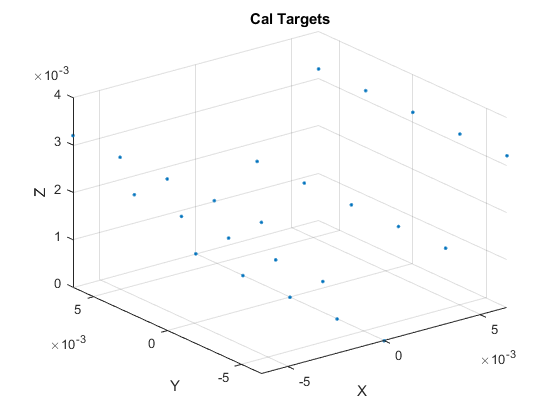

figure
plot3(xc,yc,zc,'.')
xlabel('X');ylabel('Y');zlabel('Z');grid on
title('Cal Targets')

**Using the CalTargetMultiView function, synthetic calibration images can be generated by passing in a few functions. **

**Open the calTargetMultiViw to see the input parameters:**

**The main Parameters:**

addParameter(p, 'plot', true, @islogical); % SHOW IMAGES 

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct); % Load the cameras 

addParameter(p, 'cal_dir', 'test/cal', @isstr); % Directory to Save files

addParameter(p, 'save', false, @islogical); % Save files 

addParameter(p, 'TargetFile', true, @islogical); % Save Target file for PTV

addParameter(p, 'target_3D', true, @islogical); %  3D Calibration Target. 

addParameter(p, 'plot_camera', false, @islogical); %SHOW CAMERA PLACMENT. 

addParameter(p, 'generate_ori', false, @islogical); % Generate ORI FILES FOR PTV

Then we can generate the calibration images using: 

calTargetMultiView('save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
true,'generate_ori', true,'plot_camera',true);
% or pass in the camera structure

% calTargetMultiView('cameras',CAMERAS,'save',true,'cal_dir',cal_dir,'TargetFile', true,'target_3D',...
% true,'generate_ori', true,'plot_camera',true);

## Flow Images:

    To generate images of the particle postions, we need to specify the image directory and ensure that the folder is empty. This code will specify said directory, and if it exist already, it will remove it.

img_dir  = [work_dir,'/img'];
if exist(img_dir)
% Remove the exiting img folder
    disp('exist')
    rmdir(img_dir,'s')
    disp('Removed image directory')
end

### Data Structure for Image generation

We need to pass data into the makeImageUniversal function. 

The data must be in a structure with fields,x,y,z. Where x,y,z are matrices containing the particle locations in time. 

Example: if is in the form X = [ 70x100 ] then 70 is the number of time steps and 100 is the number of particles and or trajectories.

Therefore, X(1,:) contains all the X locations of all the particles at time t=1. 

Once we have the matrices X,Y,Z, they must be packed intro a data structure. The data structure follows the form:

test_data.x = X;

test_data.y = Y;

test_data.z = Z ;

**Here, we will use a function which gets the turbulent. **

[X,Y,Z] = Get_turb_data(data_name,time,ntraj)

[X,Y,Z] = Get_turb_data('test',70,100);
% scale the data set 
X=.01*X;
Y=.01*Y;
Z=.01*Z;
% SHIFT
X = (X - mean(mean(X)));
Y = (Y - mean(mean(Y)));
Z = (Z - min(min(Z)));
% pack into a structure. 
test_data.x = X;
test_data.y = Y;
test_data.z = Z;

Note we are scaling and shifting the data such that it fits into our synthetic experiment. 

% plot for visual understanding
figure
plot3(X,Y,Z,'.')
title('Test data'); xlabel('X');ylabel('Y');zlabel('Z');grid on

**Then we can generate the images makeImage_universal. **

However, Like many of the other functions we can pass in parameters.

addParameter(p, 'cameras', defaultCameraArrangement(), @isstruct);

addParameter(p, 'outdir', '.', @isstr); % Where to Save 

addParameter(p, 'particleDiameterMean', 2*sqrt(8), @isnumeric); % 1.5 particleDiameterMean

addParameter(p, 'particleDiameterStdDev', 0.10 * sqrt(8), @isnumeric); %  particleDiameterStdDev

addParameter(p, 'beamStdDev', 0.05, @isnumeric); % Beam Standard dev

addParameter(p, 'BeamPlaneZ', 0, @isnumeric); % Bean plane

addParameter(p, 'save', false, @islogical); % Save Images

addParameter(p, 'plot', true, @islogical); % Plot the image sequence as it is rendered?

addParameter(p, 'data', [], @isstruct); % Our input data

**The default values can be modified by passing in the parameter. **

Here we will save the image the image sequence to our out directory, we wont plot the data, and well pass in the

data using 'data' and the test_data structure we made eariler. 

makeImages_universal('outdir',img_dir,'save',true,'plot',false,'data',test_data);

% or pass in the camera 
%makeImages_universal('cameras',CAMERAS','outdir',img_dir,'save',true,'plot',false,'data',test_data);

% Remove the tif 
remove_tif_M(img_dir);

**Go to the PTV folder we created and perform the following steps:**

1. Calibration

2. Tracking

## **Post Processing of the data Sets**

**Read in the data set**

test=[work_dir,'\res'];
% test='C:\Users\alex\Desktop\og\PTV_SYN\test\Copy_of_res';
start = 10005;
last = 10070;
dt=1/100;
min_len = 5;
%------
traj_RC=ptv_is_to_traj(test,start,last,min_len,dt);

Plot the reconstructed dataset

plot_long_trajectories(traj_RC,min_len);
v = [10 -8 2];
[caz,cel] = view(v)
title('Turbulent Flow- Reconstruction')

Get the ground truth data and put into a trajectory structure. 

Scale it by 1000, and plot them next to each other 

traj_GT = pos_to_traj(test_data.x,test_data.y,test_data.z,dt);
traj_GT_SCALED = scale_traj(traj_GT,1000);
plot_long_traject_COP(traj_GT_SCALED,'Ground Truth Scaled [mm]',traj_RC,'Reconstruction [mm]',min_len)

Lets save the data we processed into the test folder for safe keep!

% Make a folder folder our data call data sets 
data_folder_path = [folder_path,'\Datasets\']
mkdir(data_folder_path)

% Save the Ground truth Trajactory 
save([data_folder_path,'traj_GT.mat'],'traj_GT')
% Save the Ground Truth Scaled Trajectory 
save([data_folder_path,'traj_GT_SCALED.mat'],'traj_GT_SCALED')
% Save the Reconstuction Trajectory
save([data_folder_path,'traj_RC.mat'],'traj_RC')
% Save the Dataset
save([data_folder_path,'test_data.mat'],'test_data')
% And save the entire workspace work space
save([data_folder_path,'Workspace.mat'])